# Expand Example 2.14:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Consider the RLC circuit shown in the figure. Let element values be $R=5\Omega$, $L=1$ H, and $C=1/6$ F.

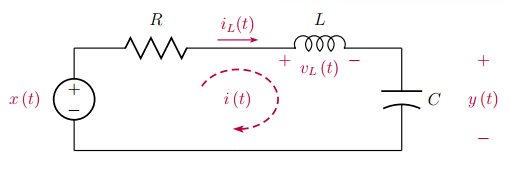 

The characteristic equation was found in Example 2.14 to be 

        
$$s^{2}+5s+6=0$$


The homogeneous solution is in the form

        
$$y_{h}(t)=c_{1}\,e^{-2t}+c_{2}\,e^{-3t}$$


Experiment by changing capacitor voltage amd inductor current at time $t=0$.

y0 = 1.5; % Initial capacitor voltage
i0 = 2; % Initial inductor current

Imposing the initial conditions yields

        $c_{1}+c_{2}=y_{0}$   and   $-2c_{1}-3c_{2}=\frac{i_{0}}{C}$

Determine and graph the natural response $y_{h}(t)$.

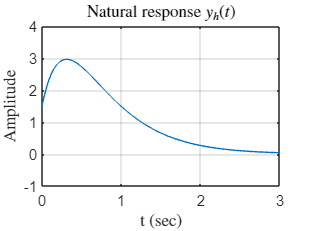

A = [1,1;-2,-3];  
B = [y0;6*i0];
C = A\B;         % Solve the eqns for c1 and c2
t = [0:0.01:3];  % Vector of time instants
yh = C(1)*exp(-2*t)+C(2)*exp(-3*t);  % Natural response
plot(t,yh); grid;
axis([0,3,-1,4]);
set(0,'defaultTextInterpreter','latex')
title('Natural response $y_{h}(t)$');
xlabel('t (sec)'); 
ylabel('Amplitude');

set(0,'defaultTextInterpreter','tex')